Steady State

clc
clear

data_steady = readmatrix("Data/DroneSteadytestNyPid 1.csv");
data_steady(:,6:end) = data_steady(:,6:end)/1000;
Data_steady = rmmissing(data_steady);

k_steady = 500;
l_steady = 300;

steady_ref_x = 0;
steady_ref_y = 0;
steady_ref_z = 1;

measTime_steady = (length(Data_steady)-l_steady-k_steady)/50;
x_steady = linspace(0,measTime_steady,length(Data_steady)-l_steady-k_steady);

x_data_steady = Data_steady(1+k_steady:end-l_steady,6);
y_data_steady = Data_steady(1+k_steady:end-l_steady,7);
z_data_steady = Data_steady(1+k_steady:end-l_steady,8);

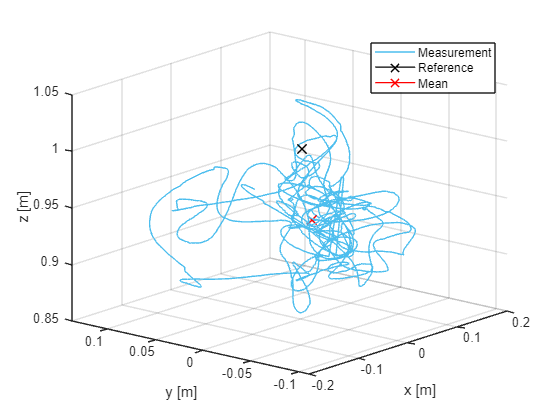

figure()
hold on

p1 = plot3(x_data_steady,y_data_steady,z_data_steady);
p1.LineStyle = "-";
p1.Color = [0.3010 0.7450 0.9330];

p2 = plot3(0,0,1);
p2.Marker = "x";
p2.Color = "black";
p2.LineWidth = 1;
p2.MarkerSize = 10;

p3 = plot3(mean(x_data_steady),mean(y_data_steady),mean(z_data_steady));
p3.Marker = "x";
p3.Color = "red";
p3.LineWidth = 1;
p3.MarkerSize = 10;

xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
legend({'Measurement','Reference','Mean'},"Location","northeast")
grid on
hold off

view([-50 20])
saveas(gcf,'Images/Accept_Steady_All_Pos','epsc')

figure()
hold on
zmean = mean(z_data_steady)

zmean = 0.9391

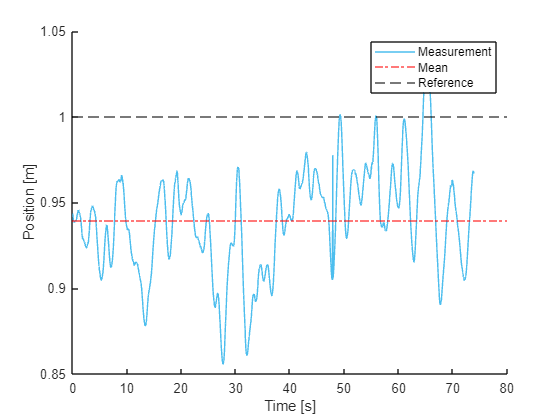

yline(zmean,"-.red");
yline(1,"--black");
plot(x_steady,z_data_steady,"Color",[0.3010 0.7450 0.9330])
legend({'Mean','Reference','Measurement'},"Location","northeast")
ylabel("Position [m]")
xlabel("Time [s]")
hold off
saveas(gcf,'Images/Accept_Steady_Z','epsc')

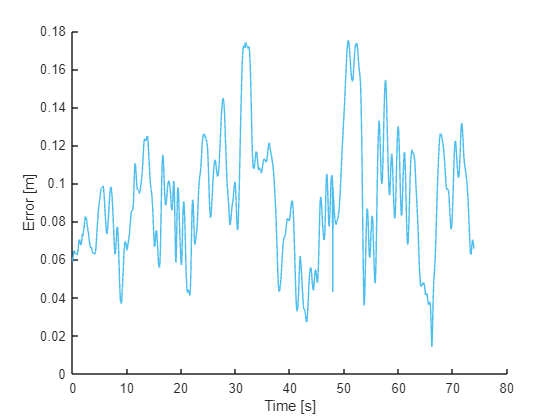

Steady_norm_data = vecnorm([(x_data_steady).'; (y_data_steady).'; (z_data_steady-steady_ref_z).'],2);
% ref_steady = norm([0,0,1],2);
% SSR_Analyse = stepinfo(Steady_norm_data,x_steady,ref_steady)
figure()
hold on
plot(x_steady,Steady_norm_data,"Color",[0.3010 0.7450 0.9330])
hold off
ylabel("Error [m]")
xlabel("Time [s]")

%saveas(gcf,'Images/Accept_Steady_Error','epsc')
mean(Steady_norm_data)

ans = 0.0916

max(Steady_norm_data)

ans = 0.1752

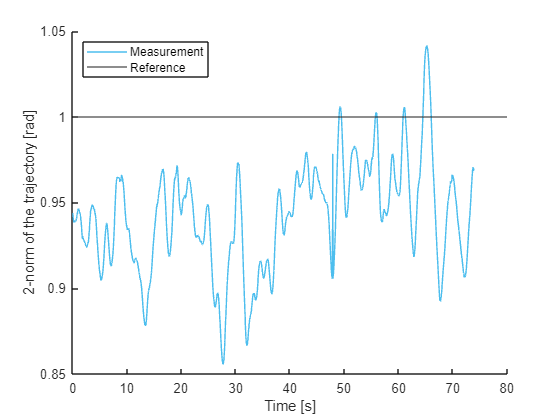

Steady_norm_data = vecnorm([(x_data_steady).'; (y_data_steady).'; (z_data_steady).'],2);
ref_steady = norm([0,0,1],2);
% SSR_Analyse = stepinfo(Steady_norm_data,x_steady,ref_steady)
figure()
hold on
plot(x_steady,Steady_norm_data,"Color",[0.3010 0.7450 0.9330])
hold off
yline(ref_steady)
ylabel("2-norm of the trajectory [rad]")
xlabel("Time [s]")
legend({'Measurement','Reference'},"Location","northwest")
saveas(gcf,'Images/Accept_Steady_Error','epsc')

mean(Steady_norm_data)

ans = 0.9417

max(Steady_norm_data)

ans = 1.0417

Step

data_step = readmatrix("Data\DroneSteptestNyPid 20cm.csv");
data_step(:,6:end) = data_step(:,6:end)/1000;
Data_step = rmmissing(data_step);

k_step = 250;
l_step = 200;

step_ref_x = 0;
step_ref_y = 0;
step_ref_z = 1;

step_size_x = -0.2;
step_size_y = -0.2;
step_size_z = 0.2;

Step_time = 200; %step happens at this sample nr.
Samp = 1/50; %sample freq

measTime_step = (length(Data_step) - l_step - k_step) / 50;
x_step = linspace(0,measTime_step,length(Data_step) - l_step - k_step);

x_data_step = Data_step(1 + k_step:end - l_step,6);
y_data_step = Data_step(1 + k_step:end - l_step,7);
z_data_step = Data_step(1 + k_step:end - l_step,8);

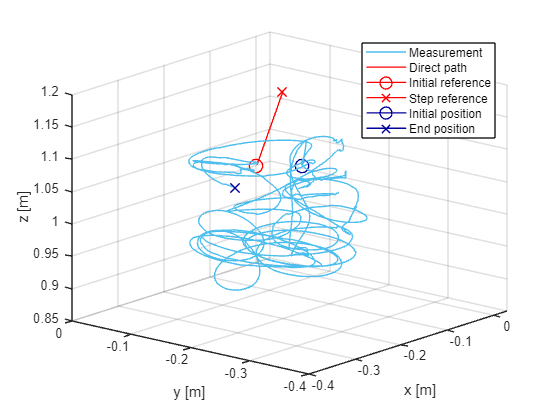

figure()
hold on

p4 = plot3(x_data_step,y_data_step,z_data_step);
p4.LineStyle = "-";
p4.Color = [0.3010 0.7450 0.9330];

p5 = plot3([0,-0.2],[0,-0.2],[1,1.2]);
% p5.Marker = "";
p5.Color = "red";
p5.LineWidth = 1;
p5.MarkerSize = 10;

p6 = plot3(0,0,1);
p6.Marker = "o";
p6.Color = "red";
p6.LineWidth = 1;
p6.MarkerSize = 10;

p7 = plot3(-0.2,-0.2,1.2);
p7.Marker = "x";
p7.Color = "red";
p7.LineWidth = 1;
p7.MarkerSize = 10;

p8 = plot3(x_data_step(1),y_data_step(1),z_data_step(1));
p8.Marker = "o";
p8.LineStyle = "-";
p8.Color = [0.0 0 153/255];
p8.LineWidth = 1;
p8.MarkerSize = 10;

p9 = plot3(x_data_step(1764),y_data_step(1764),z_data_step(1764));
p9.Marker = "x";
p9.LineStyle = "-";
p9.Color = [0.0 0 153/255];
p9.LineWidth = 1;
p9.MarkerSize = 10;

xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
legend({'Measurement','Direct path','Initial reference','Step reference','Initial position','End position'},"Location","northeast")
grid on
hold off
view([-50 20])

saveas(gcf,'Images/Accept_Step_All_Pos','epsc')

figure()
hold on
zmean_step = mean(Data_step(1+Step_time+k_step:end-l_step,8))

zmean_step = 1.0256

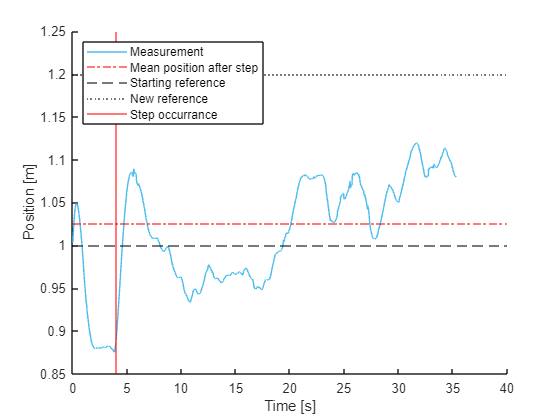


yline(zmean_step,"-.red");
yline(1,"--black");
yline(1.2,":black");
plot(x_step,z_data_step,"Color",[0.3010 0.7450 0.9330])
xline(Step_time*Samp,"-red");
ylim([0.85 1.25])
legend({'Mean position after step','Starting reference','New reference','Measurement','Step occurrance'},"Location","northwest")
ylabel("Position [m]")
xlabel("Time [s]")
hold off
saveas(gcf,'Images/Accept_Step_z','epsc')

ref_norm_data1 = vecnorm([(x_data_step).'; (y_data_step).'; (z_data_step).'],2);
ref_step = norm([0.2,0.2,1.2],2)

ref_step = 1.2329

figure()
plot(x_step,ref_norm_data1,"Color",[0.3010 0.7450 0.9330])
xline(Step_time*Samp,"-red");
ylabel("2-norm of the trajectory [rad]")
xlabel("Time [s]")
yline(ref_step)
legend({'Measurement','Step occurrance','Reference'},"Location","northeast")
SR_Analyse = stepinfo(ref_norm_data1,x_step,ref_step) 

SR_Analyse = struct with fields:
         RiseTime: 20.9022
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 1.0643
      SettlingMax: 1.1713
        Overshoot: 0
       Undershoot: 0
             Peak: 1.1713
         PeakTime: 34.2394


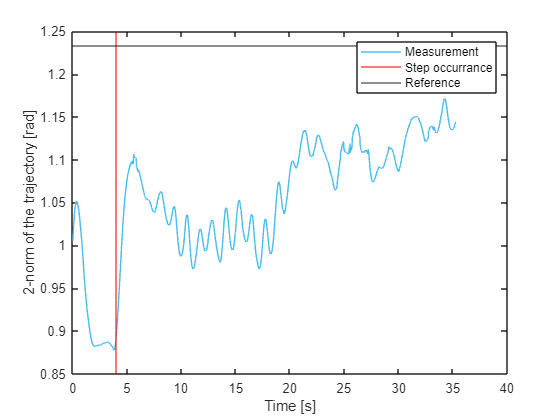

saveas(gcf,'Images/Accept_Step_Error','epsc')